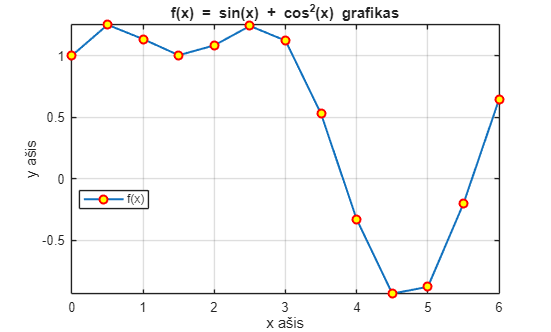

figure(1);
x1 = 0:0.5:2*pi; 
y1 = sin(x1) + cos(x1).^2; 

plot(x1, y1, '-o', 'MarkerEdgeColor', 'red', 'MarkerFaceColor', 'yellow', 'LineWidth', 1.5);
title('f(x) = sin(x) + cos^2(x) grafikas');
xlabel('x ašis');
ylabel('y ašis');

axis([min(x1) max(x1) min(y1) max(y1)]);
legend('f(x)', 'Location', 'best');
grid on;

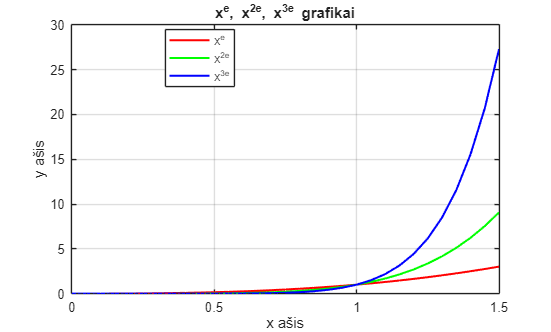

figure(2);
x2 = 0:0.05:1.5; 

y2_1 = x2.^exp(1);      
y2_2 = x2.^(2*exp(1));  
y2_3 = x2.^(3*exp(1)); 

plot(x2, y2_1, 'red-', x2, y2_2, 'g-', x2, y2_3, 'b-', 'LineWidth', 1.5);
title('x^e, x^{2e}, x^{3e} grafikai');
xlabel('x ašis');
ylabel('y ašis');
legend('x^e', 'x^{2e}', 'x^{3e}', 'Location', 'best');
grid on;

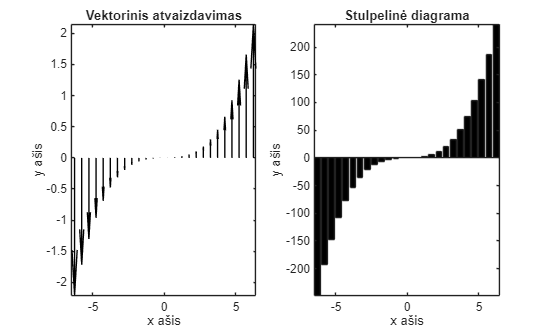

x3 = -2*pi:0.5:2*pi; 
y3 = x3.^3 + sin(x3);
figure(3);
%a
subplot(1, 2, 1);
quiver(x3, zeros(size(x3)), zeros(size(x3)), y3, 'black');
title('Vektorinis atvaizdavimas');
xlabel('x ašis');
ylabel('y ašis');
axis tight; 

%b
subplot(1, 2, 2);
bar(x3, y3, 'black');
title('Stulpelinė diagrama');
xlabel('x ašis');
ylabel('y ašis');
axis tight;

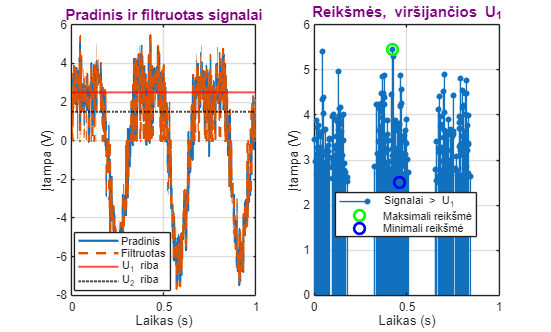

A = 4;
f = 3;
sigma = 1;
U1 = 2.5;
U2 = 1.5;
t = 0:0.001:1;
s = A*sin(2*pi*f*t) + 0.5*A*cos(4*pi*f*t);
n = sigma*randn(size(t));
s_tr = s + n;
idx_U1 = find(s_tr > U1);
reiksmes = s_tr(idx_U1);
t_reiksmes = t(idx_U1);
s_filtr = s_tr;
s_filtr(abs(s_filtr) < U2) = 0;

figure;
%a
subplot(1, 2, 1);
plot(t, s_tr, '-', 'LineWidth', 1.75); hold on;
plot(t, s_filtr, '--', 'LineWidth', 1.75);
yline(U1, 'r', 'LineWidth', 1.5);
yline(U2, 'k:', 'LineWidth', 1.5);
grid on;
title('Pradinis ir filtruotas signalai', 'Color', [0.5 0 0.5], 'FontSize', 11);
xlabel('Laikas (s)');
ylabel('Įtampa (V)');
legend('Pradinis', 'Filtruotas', 'U_1 riba', 'U_2 riba', 'Location', 'best');
xlim([0 1]);

%b
subplot(1, 2, 2);
stem(t_reiksmes, reiksmes, 'filled', 'MarkerSize', 4); hold on;

[max_val, max_idx_rel] = max(reiksmes);
[min_val, min_idx_rel] = min(reiksmes);

plot(t_reiksmes(max_idx_rel), max_val, 'go', 'MarkerSize', 8, 'LineWidth', 2);
plot(t_reiksmes(min_idx_rel), min_val, 'bo', 'MarkerSize', 8, 'LineWidth', 2);

grid on;
title('Reikšmės, viršijančios U_1', 'Color', [0.5 0 0.5], 'FontSize', 11);
xlabel('Laikas (s)');
ylabel('Įtampa (V)');
legend('Signalai > U_1', 'Maksimali reikšmė', 'Minimali reikšmė', 'Location', 'best');
xlim([0 1]);